La segmentació subdivideix una imatge en les seves parts constituents o objectes representatius, amb la finalitat de separar les parts d'interés de la resta de la imatge. El nivell en el qual es du a terme aquesta subdivisió depèn del problema a resoldre en qüestió, i hi han moltes modalitats i tècniques per aconseguir el resultat desitjat. 

L'objectiu d'aquesta pràctica, per tant, és profunditzar en les diferents modalitats de segmentació, així com cercar i aplicar diversos algoritmes d'aquestes modalitats en imatges mèdiques, per tal d'observar el seu efecte.

La pràctica es divideix en dues parts. La primera consisteix únicament en la recerca, classificació i explicació de les modalitats de segmentació i de un parell d'algoritmes de cada modalitat, mentre que la segona part tracta d'escollir tres algoritmes de segmentació citats en la primera part i aplicar-los en imatges mèdiques donades.

- **PART 1: RESEARCH WORK**

**1) Clustering Based Segmentation:**

Aquest tipus de segmentació es refereix al procés d'agrupació de mostres per tal de que cada mostra sigui semblant a les demés mostres del grup. Els grups s'anomenen "clústers".  Distinguim dos tipus de Clustering Based Segmentation: els que pertanyen a "Hard Clustering" o a "Fuzzy Clustering". 

En el cas del Hard Clustering, distinguim conjunts nítids per representar la pertinença d'elements. És a dir, la pertinença d'elements a un clúster s'evalua en tèrmes binaris segons si l'element pertany o no al conjunt. No obstant, no sempre sabem amb seguretat si un element pertany o no a un grup. En aquests casos, quan els elements no només pertanyen a un grup sinó que comparteixen una part de la pertinença a diversos grups, s'utilitza l'agrupació difusa, és a dir la de tipus Fuzzy Clustering. Aquesta última permet l'avaluació gradual de la pertinença dels elements en un conjunt que es descriu per una funció de pertinença valorada en l'interval real [0, 1]. [2]

Un dels problemes presents en la Fuzzy Clustering és la complexitat computacional quan la quantitat de dades a analitzar resulta massa gran. 

*-**K-means* és una tècnica de classificació no supervisada (clusterització) que pertany al Hard Clustering i que agrupa objectes en *k *grups basant-se en les seves característiques. L'agrupament es realitza minimitzant la suma de distàncies entre cada objecte i el centroide del seu grup o clúster. Es sol utilitzar la distància quadràtica. S'utilitza bastant donat que és un algorisme simple i fàcil d'entendre.

L'algorisme bàsic consta de tres passos:

- Inicializació: Una vegada escollit el número de grups *k, *s'estableixen *k *centroides de les dades (es poden escollir aleatòriament).

- Assignació d'objectes als centroides: Cada objecte de les dades és assignat amb el seu centroide més proper.

- Actualizació de centroides: S'actualitza la posició del centroide de cada grup, agafant com a nou cetroide la posició del promig dels objectes que pertànyen al grup. 

Es repeteixen els passos 2 i 3 fins que els centroides no es mouen, o bé es mouen per sota d'una distància umbral en cada pas. 

A continuació, implementarem un exemple del Matlab [3]  per exemplificar i visualitzar millor aquests conceptes:

%Generem un conjunt de dades d'entrenament amb 3 distribucions :

rng('default') %Aquesta funció especifica la velocidad del generador aleatori 
               % de números MATLAB®.
X = [randn(100,2)*0.75+ones(100,2);
    randn(100,2)*0.5-ones(100,2);
    randn(100,2)*0.75]; %La funció randn genera nombres aleatoris de la distribució
                        % normal complexa estàndard. 


[idx,C] = kmeans(X,3); %Dividim les dades en 3 clústers amb kmeans. 

%Representem els clústers i els centroides dels clústers:
figure
gscatter(X(:,1),X(:,2),idx,'bgm')
hold on
plot(C(:,1),C(:,2),'kx')
legend('Cluster 1','Cluster 2','Cluster 3','Cluster Centroid')


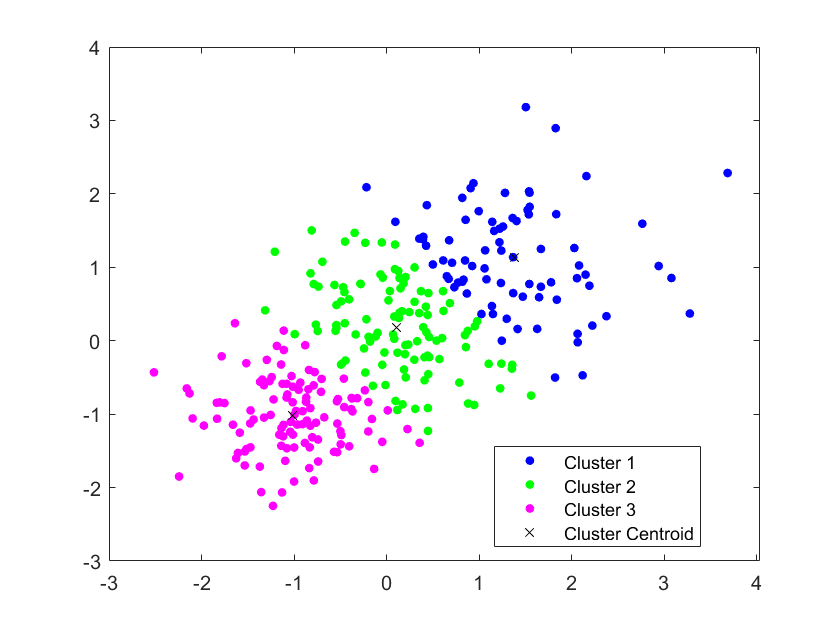

El resultat d'aplicar k-means és la agrupació de les dades en k grups (en aquest cas 3 grups), cada grup amb unes característiques semblants. 

-*Fuzzy c-means* és una tècnica d'agrupació que pertany a Fuzzy Clustering i en la qual un conjunt de dades s'agrupa en N clústers amb cada punt de dades del conjunt de dades pertanyent a cada clúster fins a un cert grau. Per exemple, un punt de dades que es troba a prop del centre d'un clúster tindrà un alt grau de pertinença a aquest clúster, i un altre punt de dades que es troba lluny del centre d'un clúster tindrà un grau baix de pertinença a aquest clúster. [4]

L'agrupació de Fuzzy c-means es pot considerar un algorisme millor en comparació amb l'algoritme de k-means. A diferència de l'algorisme k-means, on els punts de dades pertanyen exclusivament a un clúster, en aquest cas el punt de dades pot pertànyer a més d'un clúster amb una probabilitat. [5]

**2) Edge Detection Segmentation:**

La detecció de vores o Edge Detection és una tècnica de processament d'imatges per trobar els límits dels objectes dins de les imatges. La vora és un límit entre dos regions homogènies i la detecció de vores fa referència al procés d'indentificar i localitzar discontinuïtats pronunciades en una imatge. 

Una de les aplicacions més importants és la detecció de vores per a la segmentació d'imatges. Els algorismes o tècniques de detecció de vores comuns inclouen Sobel, Canny, Prewitt, Roberts i mètodes de lògica difusa .[7], molts dels quals s'han treballat durant pràctiques anteriors. 

A continuació,comentarem un parell de tècniques per a aquest tipus de segmentació:

-Sobel: És un mètode per la detecció de vores o contorns basats en el gradient, és a dir, en la primera derivada. El gradient s'estima mitjançant l'ús d'operadors, els quals assumeixen que a les vores d'una imatge hi han píxels amb alts gradients i per tant es produirà un canvi ràpid d'intensitat en el vecotr gadient. 

L'operador de Sobel Posa ènfasi en els píxels propers al centre de la màscara i és menys sensible al soroll que altres operadors de gradients, com per exemple el Roberts. 

Amb Matlab s'implementa mitjançant la funció "edge", tal i com hem vist anteriorment i tal i com s'exemplifica a continuació:

I = imread('test\rice.png') %Llegim imatge
infoI = imageinfo('test\rice.png'); %Mostrem la seva informació i observem que 
                                    % ja està en escala de grisos.
figure;imshow(I);colorbar %Mostrem imatge


IBS = edge(I, 'Sobel'); %Apliquem l'algorisme de Sobel.
imshow(IBS)


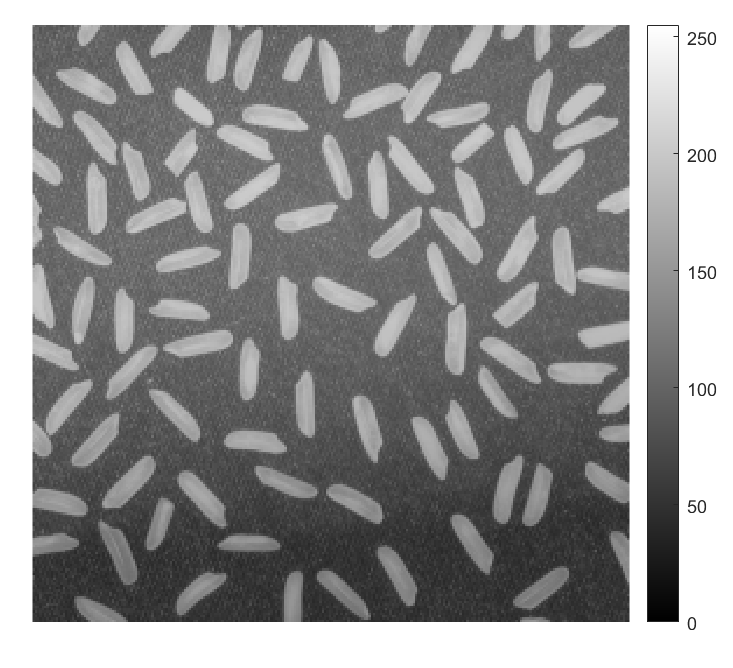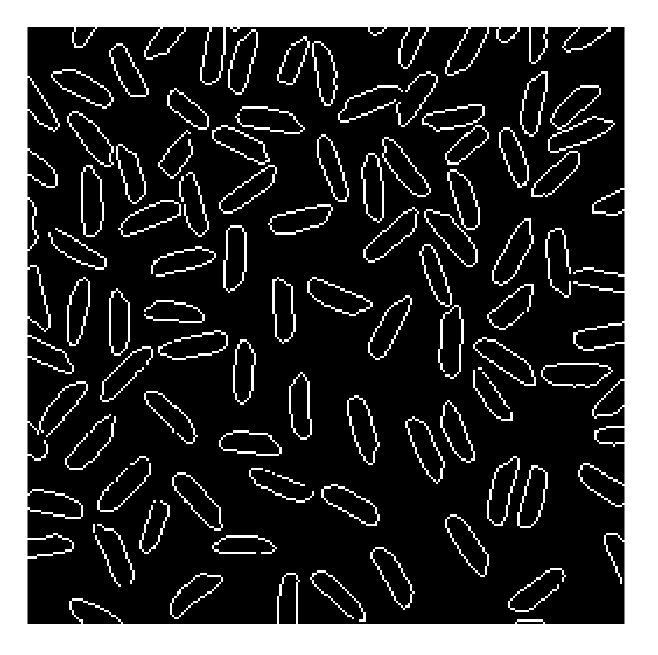

-Canny: És un tipus de detector de vores comunment utilitzat per la seva eficàcia.  Utilitza un algorisme iteratiu i un filtre basat en la primera derivada d'una gaussiana. No es veu fàcilment afectat pel soroll i detecta contorns molt fins, per tant presenta resultats amb molt detall. A continuació, veurem un petit exemple:

I2 = imread('medical\brain.jpg') %Llegim imatge
infoI2 = imageinfo('medical\brain.jpg'); %Mostrem la seva informació i observem que ja està 
                                         % en escala de grisos.
                                         
figure;imshow(I2);colorbar %Mostrem imatge

%Observem que està en escala a color per tant la passem a escala de grisos:
Ibg=rgb2gray(I2)
figure;imshow(Ibg);colorbar

IBS2 = edge(Ibg, 'Canny'); %Apliquem l'algorisme de Canny.
imshow(IBS2)


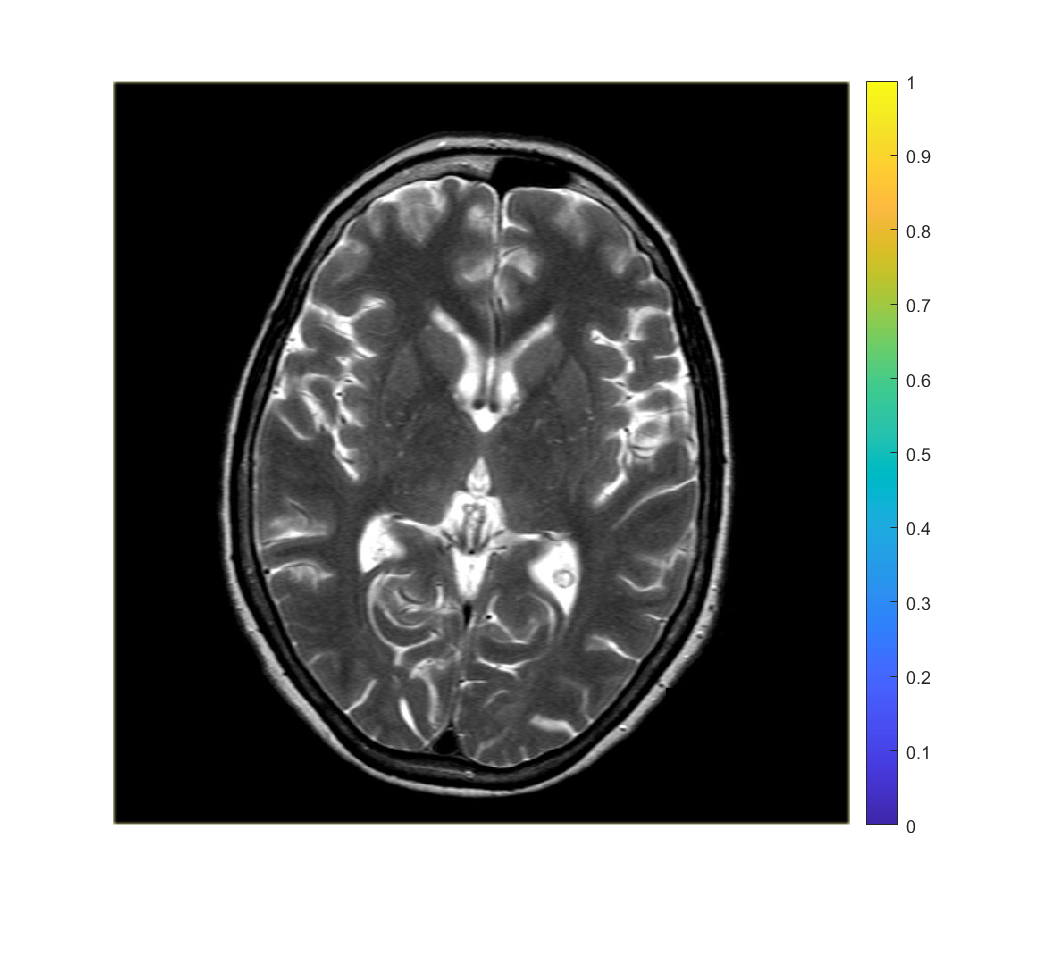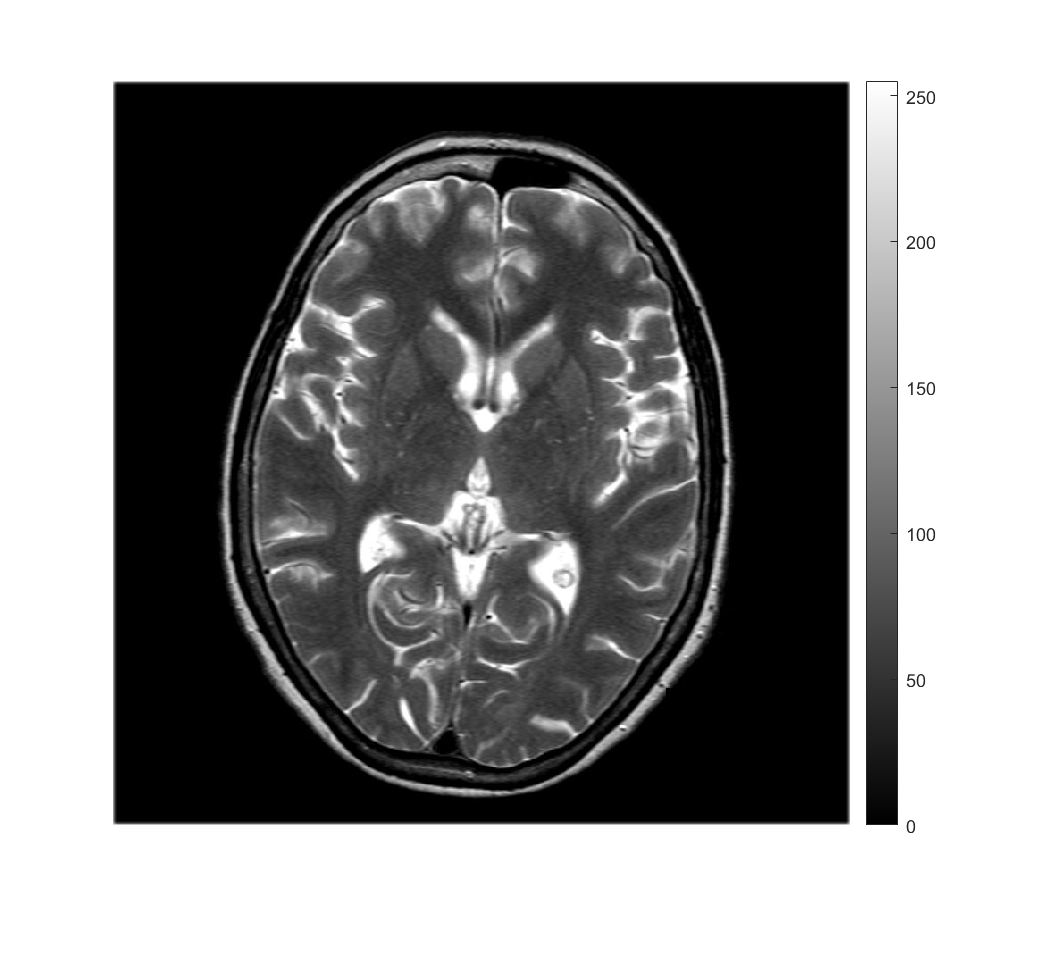

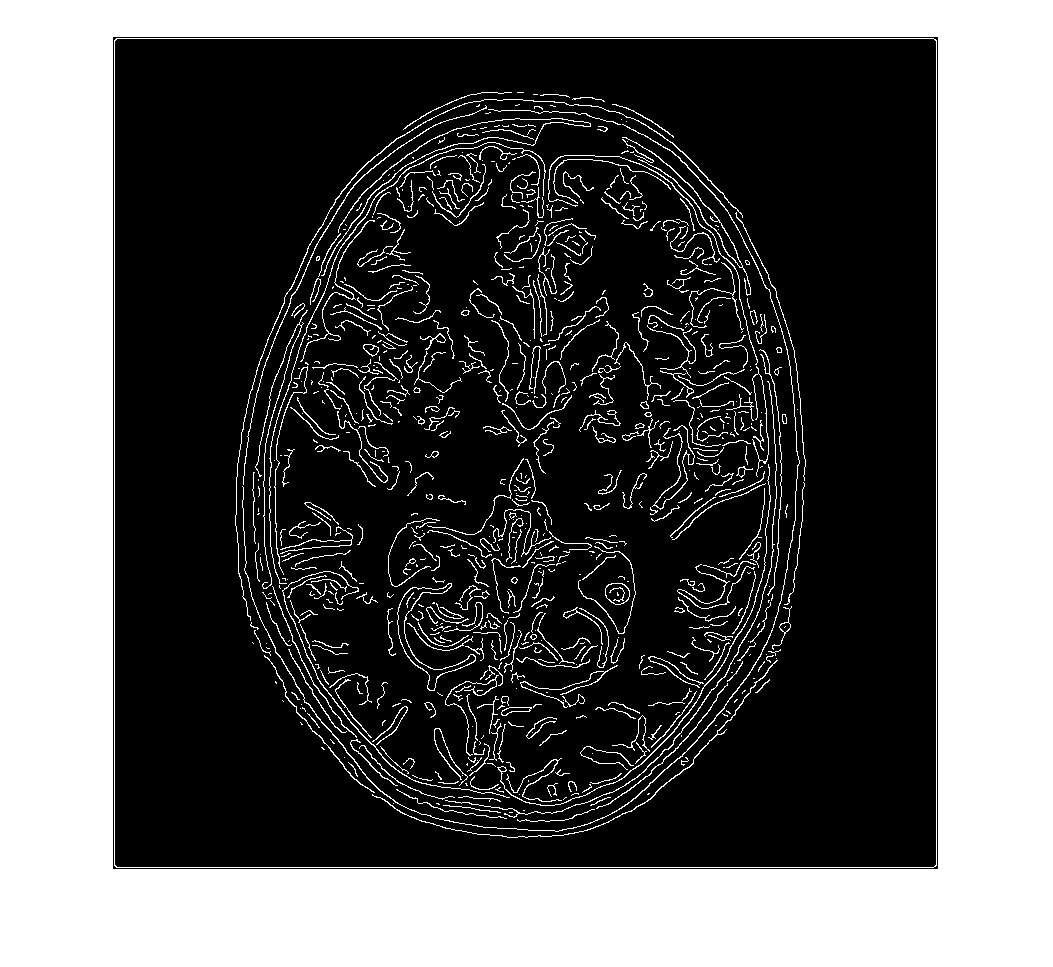

**3) Region based segmentation**

**4) Threshold Based Segmentation.**

**5) Pixel based segmentation**

....

os puede ser de ayuda : [https://es.mathworks.com/discovery/image-segmentation.html](https://es.mathworks.com/discovery/image-segmentation.html)

- **PART 2: APLICAR ALGORITMES DE SEGMENTACIÓ:**

A continuació, si'implementarán tres algoritmes de les tècniques explicades anteriorment en imatges mèdiques únicament. 

- Primerament, es segmentarà mitjançant k-means [8]:

Es segmentarà la imatge del cervell en 3 regions mitjançant k-means clustering. 

Matlab conté varies funcions per dur a terme això, entre elles destaca la següent, la qual segmenta la imatge que indiquem en 

% [L,centers] = imsegkmeans(I,k) segmenta la imatge en escala de grisos I en k clústers 
% mitjançant k-means clustering i retorna la sortida segmentada anomenada L. 
% K ha de ser un número postitiu i enter.A més, retorna també les ubicacions del centroide
% del clúster (centres).

[L,Centers] = imsegkmeans(Ibg,3); 
B = labeloverlay(Ibg,L);
imshow(B)
title("Imatge segmentada")

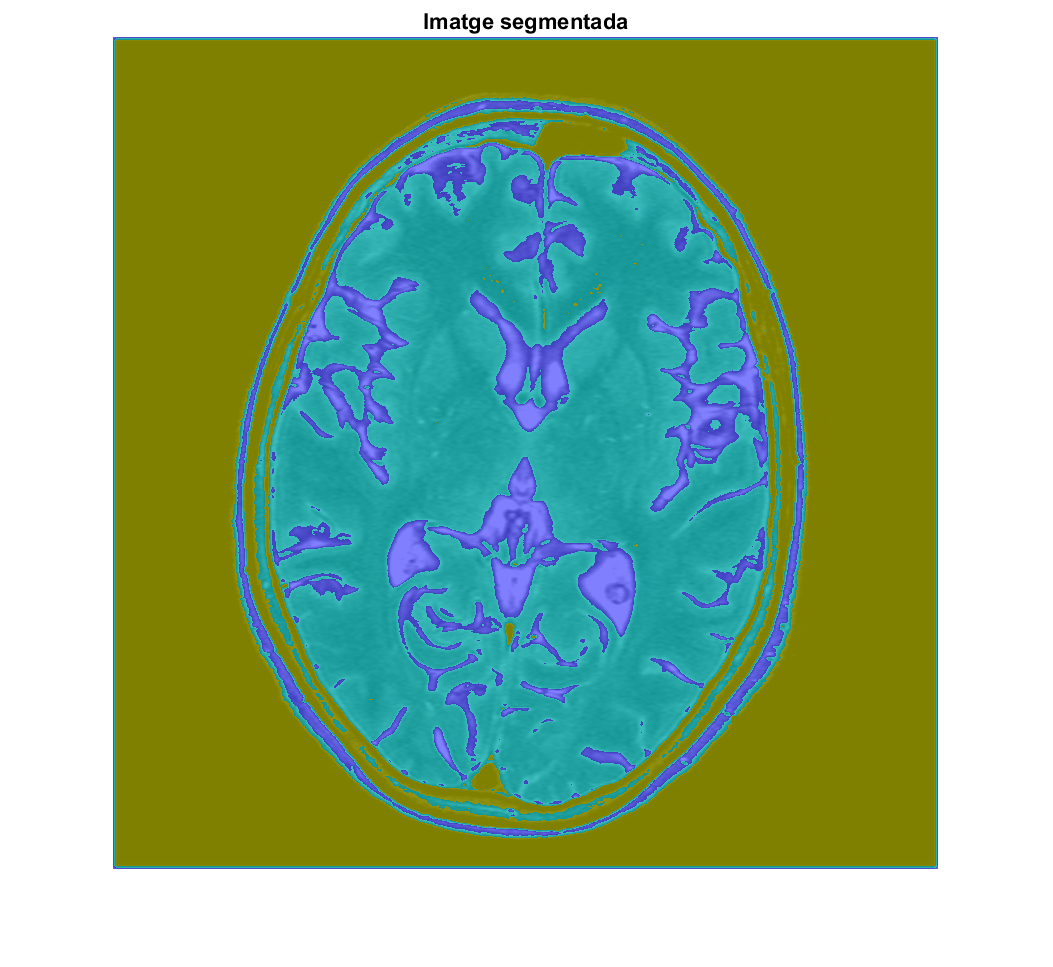

Podem observar clarament com la imatge està separada en tres regions de tres colors diferents. També ens adonem de que aquelles regions d'un color similar en la imatge original, han quedat agrupades per el mateix color després de la segmentació, fet que coincideix amb la literatura explicada en la primera part, on  s'indicava que en un mateix grup hi havien mostres semblants.

A continuació, anem a augmentar el número de clústers per veure l'efecte causat:

[S,Centers] = imsegkmeans(Ibg,6) %No posem ";" per veure les ubicacions dels centres.
C = labeloverlay(Ibg,S);
imshow(C)
title("Imatge segmentada")

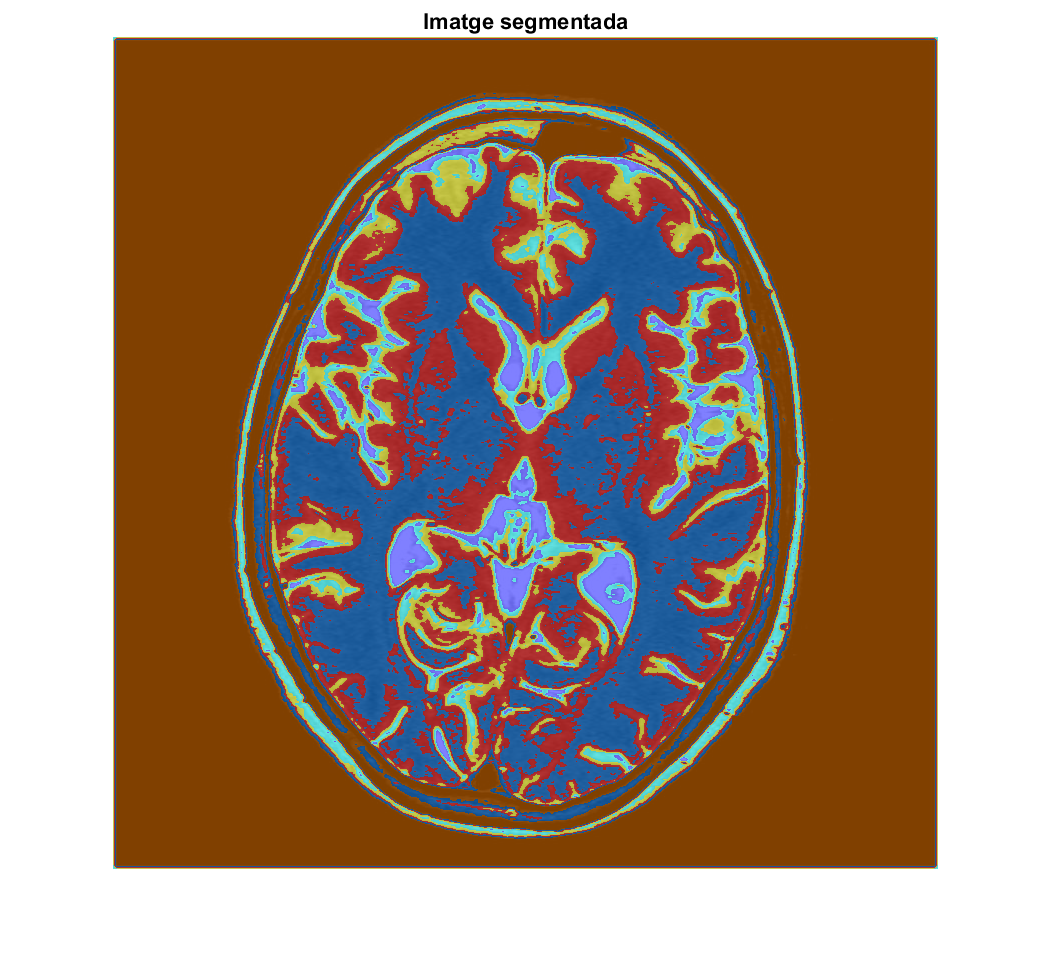

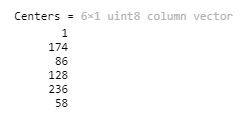

Amb sis clústers observem la imatge segmentada en 6 regions de 6 colors diferents. Això pot ser molt interessant ja que hi han regions a la imatge que ens semblen del mateix color (i per tant erròniament podem pensar que és el mateix tipus de teixit, per exemple) i al aplicar la segmentació ens adonem de que realment no és així. El fet de que la imatge es segmenti en pseudocolors també ajuda a millorar l'apreciació i interpretació de la imatge i dels diferents components que la composen, ja que els humans podem distinguir un major nombre de colors que de nivells de grisos. 

Seguidament, aplicarem aquesta funció amb una altre imatge d'exemple. 

Ip = imread('medical\breast.PNG') %Llegim imatge
infoIp = imageinfo('medical\breast.PNG'); %Mostrem la seva informació i observem que està en color (truecolor)
figure;imshow(Ip);colorbar %Mostrem imatge

%Passem a escala de grisos:
Ipg=rgb2gray(Ip)
figure;imshow(Ipg);colorbar

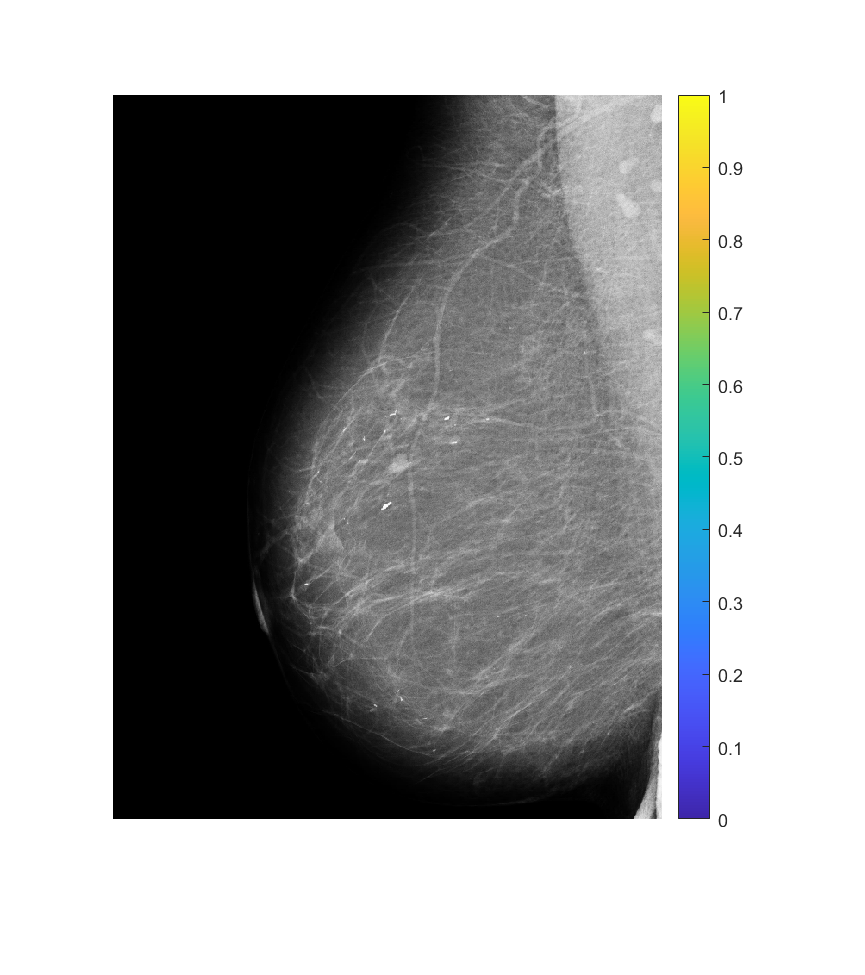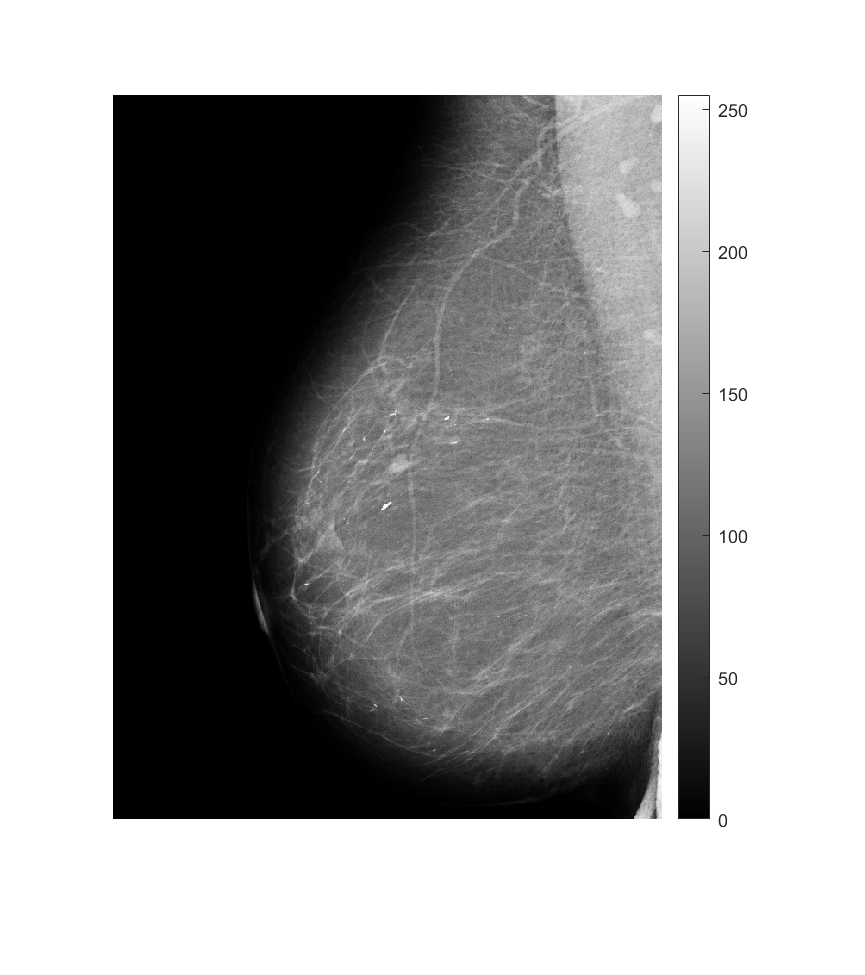

[P,Centers] = imsegkmeans(Ipg,3);
[M,Centers]=imsegkmeans(Ipg,4);
N = labeloverlay(Ipg,P);
Q=labeloverlay(Ipg,M);

figure;subplot(1,2,1);imshow(N);title('Imatge segmentada amb k=3');
subplot(1,2,2);imshow(Q);title('Imatge segmentada amb k=4')

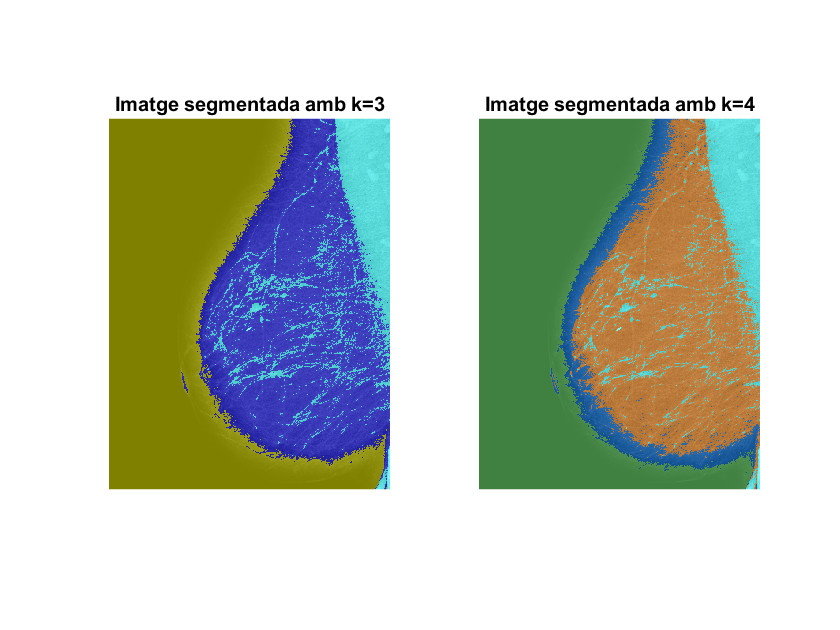

En aquesta imatge de mamografía, les diferents regions augmenten amb el número de clústers i es poden observar els diferents teixits i vasos sanguinis. Creiem que aquest mètode de segmentació pot ser molt útil per tal de detectar calcificacions en les mamografíes, ja que les calcificacions apareixerien d'un color diferent a la resta i serien fàcilment apreciables a ull nu. També podria ser útil per segmentar cèl·lules canceroses o tumors i medir la seva gravetat.

**REFERÈNCIES**

[1] Toranzo Lorca, Gustavo & Arzola-Ruiz, José & Barzaga, Osvaldo. (2010). Segmentación de Imágenes Médicas Digitales mediante 

Técnicas de Clustering. 15 Convención Científica de Ingeniería y Arquitectura. URL: [https://www.researchgate.net/publication/235420282_Segmentacion_de_Imagenes_Medicas_Digitales_mediante_Tecnicas_de_Clustering](https://www.researchgate.net/publication/235420282_Segmentacion_de_Imagenes_Medicas_Digitales_mediante_Tecnicas_de_Clustering)

[2] Anjana Gosain, Sonika Dahiya, Performance Analysis of Various Fuzzy Clustering Algorithms: A Review, Procedia Computer Science, Volume 79,

2016, Pages 100-111, ISSN 1877-0509, URL:

[https://www.sciencedirect.com/science/article/pii/S1877050916001459](https://www.sciencedirect.com/science/article/pii/S1877050916001459)

[3] MATLAB help center. URL: [https://es.mathworks.com/help/stats/kmeans.html#d123e13375](https://es.mathworks.com/help/stats/kmeans.html#d123e13375)

[4] MATLAB help center. URL: [https://es.mathworks.com/help/fuzzy/fuzzy-c-means-clustering.html](https://es.mathworks.com/help/fuzzy/fuzzy-c-means-clustering.html)

[4] Satyam Kumar, Fuzzy C-means clustering-is it better than k-means clustering?, Towards data science (2021), URL:

[https://towardsdatascience.com/fuzzy-c-means-clustering-is-it-better-than-k-means-clustering-448a0aba1ee7](https://towardsdatascience.com/fuzzy-c-means-clustering-is-it-better-than-k-means-clustering-448a0aba1ee7)

[6] Yağmur Çiğdem Aktaş, Image segmentation with Clustering,  Towards data science (2021), URL:

[https://towardsdatascience.com/image-segmentation-with-clustering-b4bbc98f2ee6](https://towardsdatascience.com/image-segmentation-with-clustering-b4bbc98f2ee6)

[7] MATLAB help center. URL: [https://es.mathworks.com/discovery/edge-detection.html](https://es.mathworks.com/discovery/edge-detection.html)

[8] MATLAB help center. URL: [https://es.mathworks.com/help/images/ref/imsegkmeans.html](https://es.mathworks.com/help/images/ref/imsegkmeans.html)